# **Simpson 1/3 Rule **

Simpson’s 1/3 rule results when a second-order interpolating polynomial is substituted

into $I=\int_a^b f\left(x\right)\textrm{dx}\approx \int_a^b f_n \left(x\right)\textrm{dx}$ 

### 
$$I=\int_a^b f\left(x\right)\textrm{dx}\cong \int_a^b f_2 \left(x\right)\textrm{dx}$$


After integration and algebraic manipulation, the following formula results

### 
$$I\cong \frac{h}{3}\lbrack f\left(x_0 \right)+4f\left(x_1 \right)+f\left(x_2 \right)\rbrack$$


where for this case $h=\frac{b-a}{2}$ This equation is known as Simpson’s 1/3 rule. It is the second Newton-Cotes closed integration formula. The label “1/3” stems from the fact that h is divided by 3.Simpson’s 1/3 rule can also be expressed using the format            

### `The Multiple Application Of Simpson 1/3 Rule``:`

Just as with the trapezoidal rule, Simpson’s rule can be improved by dividing the integration

interval into a number of segments of equal width

####  
$$h=\frac{b-a}{n}$$


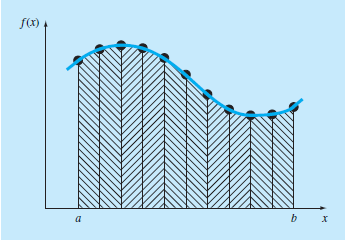

General Simpson 1/3 rule is :

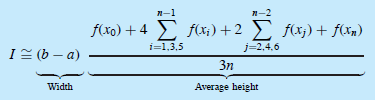

 **Note that the method can be employed only if the number of segments is even**.

### **Step 1 : Definig the Function **

First step of simpson's rule is to define the function and it's lower bound and upper bound which is **a** and **b** . Then we have to define the number of sagments **n**.

For defining the function we have used inline function from matlab.In **input **we have given two parameter .1st parameter is **prompt** and the 2nd one indicates that the input is a **string.**Then using inline we have converted the string to a function.

f_input =input("Enter your function : ","s") ;           %Function of variable x
f = inline(f_input)  ;                                   %Using inline function
a = input ( "Value of a=");
b = input ( "Value of b=");
n = input ( "Value of n(must be even ) =");

### **Step 2 : Finding Step size**

We will divide the difference between upperbound and lowerbound into n sections and we called this **h** .This value is called step size .We have to find the functional value starting from lower bound and evrey time it will increase the amount of step size upto upper bound 

h = ( b-a) / n ;

### **Step 3 :Calculating the sum of initial and final boundary value of Function**

From the ultimate simpson's rule we can see there is no co-efficient in the functional  extreme boundary value. So we will sum up two extreme functional value and called it **s**

s = f(a) + f(b);

### **Step 4 : Declaring the initial sum value of even and odd points **

We have to sum up all the even point functional value and multiply it by 4 and all the odd point functional value and multiply it by 2 . So we declare two variable as s_even and s_odd and sets it's initial value 0

 s_even = 0 ;
 s_odd = 0 ;

### **Step 5 : Calculating the total  sum value odd points(s_odd)** 

In this step we will calculate the final value of s_odd. Our odd points will start  from 1 and increase by 2 upto the previous value of upperbound. We will use for loop to generate those odd values. Inside the for loop we will calculate the functional value of those particular point and multilpy it by 4, named this as temp_values.After that we will calculate the latest s_odd by adding temp_values with previous temp_values and end our for loop.

for i = 1 : 2 : n-1 
     temp_values =4* f (a + i*h); 
     s_odd = s_odd + temp_values;
     
 end 

### **Step 6 : Calculating the total  sum value of even points(s_even)**

In this step we will calculate the final value of s_even. Our even points will start from 2 and increase by 2 upto the previous value of upperbound. We will use for loop to generate those even values. Inside the for loop we will calculate the functional value of those particular point and multilpy it by 2, named this as temp_values.After that, we will calculate the latest s_even by adding temp_values with previous temp_values and end our for loop

for i = 2 : 2 : n-1 
     temp_values =2* f (a + i*h) ;
     s_even  = s_even + temp_values;
     
 end 

### **Step 7 : Final intigration value using simpson's rule**

As we have calculated the sum of boundary values ,all even functional values multiplying by 2 and all odd fuctional values multiplying by 4 .We will add all those values and multiply it by $\frac{b-a}{3n}$.Finally we will print the the integration value using **frpintf** function

intigration_value = ((b-a)/(3*n)) * ( s+s_even+ s_odd) ;
fprintf("The Value of integration using Simpson 1/3 Rule is %f",intigration_value);
